%Phys 434 Lab 1
%Student name:      Natalie Shen
%Student UW NetID:  shnnat@uw.edu
%Student ID#:       1422640
%Date: 10/8/19

%%clear all; close all; clc
%x = [5]
%x = randn(1,5)
%mu = mean(x)
%sigma = std(x)
%sigma = 
%p = normcdf(x, mu, sigma)
%q = norminv(p, mu, sigma)


%1B
x = [1 2.7 3]

x =     1.0000    2.7000    3.0000


Y = 1 - erfc(x)

Y =     0.8427    0.9999    1.0000




%1C

z = 1 - erfcinv(Y)

z =     0.8597    0.9999    1.0000


mu = 0;
%sigma = 2;
sigma = 1

sigma = 1

p = makedist("Normal", "mu", mu, "sigma",sigma)

p =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


x = linspace (-10, 10, 100)

x =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


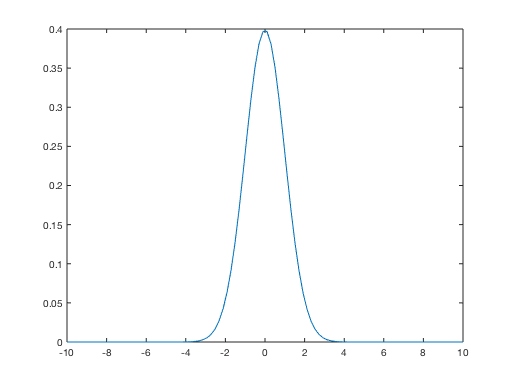

plot(x,pdf(p,x),"LineWidth",.5)

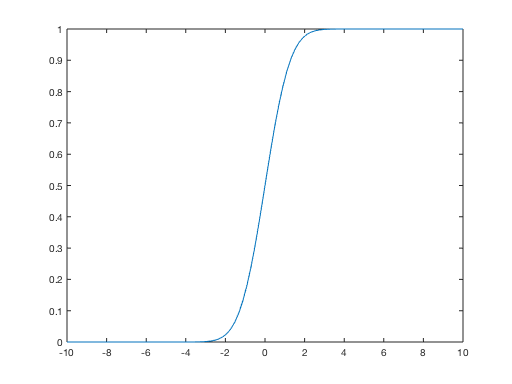

plot(x,normcdf(x,mu,sigma))


%1D

%The minus sigma (assuming we're still recording sigma from the center)
%means that we have gone below average. Probability is equal
%to its positive sigma counterpart


%2A

%Lognormal distribution, continous probability distribution
%of a vector/function/variable whos logarithm is 
%normally distributed


%2B

%sigma =4;
sigma = 5

sigma = 5

pd = makedist('Lognormal','mu',log(1000),'sigma',sigma)

pd =   LognormalDistribution

  Lognormal distribution
       mu = 6.90776
    sigma =       5



x = linspace(0,.5,50)

x =          0    0.0102    0.0204    0.0306    0.0408    0.0510    0.0612    0.0714    0.0816    0.0918    0.1020    0.1122    0.1224    0.1327    0.1429    0.1531    0.1633    0.1735    0.1837    0.1939    0.2041    0.2143    0.2245    0.2347    0.2449    0.2551    0.2653    0.2755    0.2857    0.2959    0.3061    0.3163    0.3265    0.3367    0.3469    0.3571    0.3673    0.3776    0.3878    0.3980    0.4082    0.4184    0.4286    0.4388    0.4490    0.4592    0.4694    0.4796    0.4898    0.5000


y = pdf(pd,x)

y =          0    0.5571    0.3794    0.3004    0.2535    0.2217    0.1984    0.1805    0.1661    0.1543    0.1444    0.1359    0.1286    0.1222    0.1165    0.1114    0.1068    0.1027    0.0989    0.0954    0.0923    0.0893    0.0866    0.0841    0.0817    0.0795    0.0775    0.0755    0.0737    0.0720    0.0704    0.0688    0.0674    0.0660    0.0646    0.0634    0.0622    0.0610    0.0599    0.0588    0.0578    0.0569    0.0559    0.0550    0.0541    0.0533    0.0525    0.0517    0.0510    0.0503


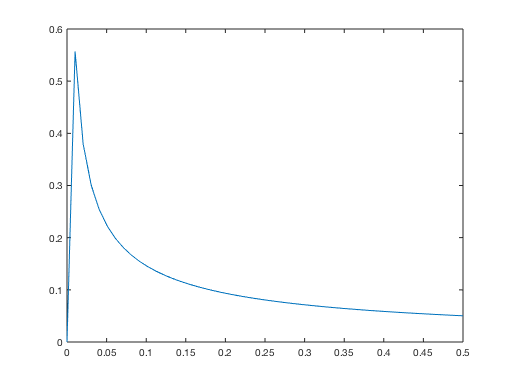

x =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


y =          0    0.0870    0.1671    0.2412    0.3102    0.3747    0.4353    0.4925    0.5465    0.5978    0.6466    0.6931    0.7376    0.7802    0.8210    0.8602    0.8979    0.9343    0.9694    1.0033    1.0361    1.0678    1.0986    1.1285    1.1575    1.1856    1.2130    1.2397    1.2657    1.2910    1.3157    1.3398    1.3633    1.3863    1.4088    1.4307    1.4523    1.4733    1.4939    1.5141    1.5339    1.5533    1.5724    1.5911    1.6094    1.6275    1.6452    1.6625    1.6796    1.6964


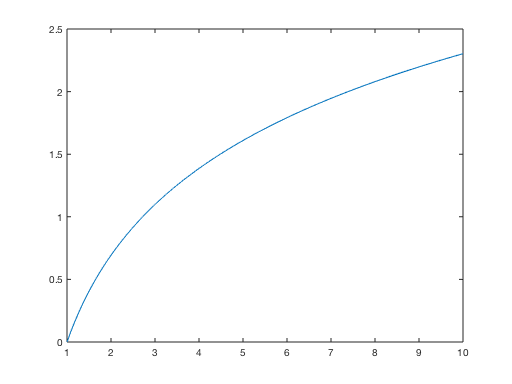


plot(x,y)